# Assignment 1 - Tensor basics

## 1. Introduction

### 1.1 Goal 

In this exercise you will work on fundamental concepts of tensors. These topics lay the ground for tensor decompositions, which are covered in Assignment 2 and Assignment 3. While most programming languages do offer native support for multilinear indexing, they seldomly offer advanced already coded more advanced routines. The main goal of this assignment is to understand these concepts and to implement them in practice.

### **1.2 Instructions**

Your tasks will be to:

- Fill out missing pieces of code in this file,

- Complete some of the functions inside the 'utils' folder,

- Answer the open questions in this file.

#### Files needed for this exercise

You will need to complete the following functions, which can be found in the 'utils' folder:

- `*vec.m                                    -` Function that vectorizes a tensor

- `*mode_n_matricization.m                   `- Function that matricizes a tensor

- `*mode_n_product.m`                                                  - Function that computes the k-mode product of a matrix and a tensor                   

- `*outer_product.m`                                                    - Function that computes the outer product of vectors

- `*outer_product_kron.m`                                          - Function that computes the outer product of vectors using the built-in `kron.m` function

- `*khatri_rao.m`                                                          - Function that computes the Khatri-Rao product of matrices

- `*frob_inner.m`                                                          - Function that computes the Frobenius inner product of two tensors.

- `*frob_norm.m`                                                            - Function that computes the Frobenius norm of a tensor

- `given/hidden_publish_results.p `                      - Hidden function that will publish your filled in `*.m` files and `*.mlx` file into a single `.pdf` file

- `given/hidden_vec.m                        -` Hidden function that vectorizes a tensor

- `given/hidden_mode_n_matricization.m       -` Hidden function that matricizes a tensor

- `given/hidden_mode_n_product.m`                           - Hidden function that computes the k-mode product of a matrix and a tensor                   

- `given/hidden_outer_product.m`                             - Hidden function that computes the outer product of vectors

- `given/hidden_outer_product_kron.m`                   - Hidden function that computes the outer product of vectors using the built-in `kron.m` function

- `given/hidden_khatri_rao.m`                                   - Hidden function that computes the Khatri-Rao product of matrices

- `given/hidden_frob_inner.m`                                   - Hidden function that computes the Frobenius inner product of two tensors.

- `given/hidden_frob_norm.m`                                     - Hidden function that computes the Frobenius norm of a tensor

- `given/hidden_check_vec.m                   -` Hidden function that vectorizes a tensor

- `given/hidden_check_mode_n_matricization.m  `- Hidden function that matricizes a tensor

- `given/hidden_check_mode_n_product.m`                - Hidden function that computes the k-mode product of a matrix and a tensor                   

- `given/hidden_check_outer_product.m`                  - Hidden function that computes the outer product of vectors

- `given/hidden_check_outer_product_kron.m`        - Hidden function that computes the outer product of vectors using the built-in `kron.m` function

- `given/hidden_check_khatri_rao.m`                        - Hidden function that computes the Khatri-Rao product of matrices

- `given/hidden_check_frob_inner.m`                        - Hidden function that computes the Frobenius inner product of two tensors.

- `given/hidden_check_frob_norm.m`                          - Hidden function that computes the Frobenius norm of a tensor

- `given/hidden_check.m`                                              - Hidden helper function that checks whether or not the answer is correct.

****indicates files you will need to complete***

Black-box implementations of these functions which you can use to debug your code can be found in the `given` folder.

% Execute this section to have access to the given black-box functions.
addpath('./given')
addpath('./utils')

### **1.3 How to get full points**

- Hand in the homework on time. Late submissions are not taken into account and will be awarded 0 points.

- You should only submit a *.pdf file and the corresponding *.mlx file (see Submission below).

- ***.zip files and *.m files are not accepted, will not be graded and will be awarded 0 points**.

- All your answers and code should be visible in the *.pdf and the *.mlx files.  If code lines exceed the page margin, make sure you break      lines in the *.mlx file.

- You are allowed to use your code and results from Assignment 1. 

- Make sure the output of your own functions and your plots are shown in the .pdf file.

- Write the explanation only where indicated and in text-form. Explanations given as comments in the code will not count towards the points awarded for the exercise. Nevertheless, we encourage you to follow good coding practice and use meaningful comments in the code. 

### **1.4 Submission**

- Run this *.mlx file including all your code and comments. 

- Uncomment and run the code block in Section 9 of this .mlx file.

- Confirm that the created file "assignment_2_exercise_2_submission.pdf" includes all your code and comments in the .mlx file and your implementation of the .m files you worked on.

- Upload the *.pdf file and this *.mlx file to Brightspace.

- *In case the above does not work*, please copy the content of your completed .m files at the bottom of this *.mlx file and subsequently go to Live Editor -> Export -> Export to .pdf. In this case, again, upload both the *.pdf file and this *.mlx file to Brightspace.

## **2. Tensors**

In the context of this course, a tensor is defined as a multilinear array [1]. For example, tensor 

$\underline{\mathbf{X}} \in \mathbb{C}^{I_1 \times I_2 \times \ldots \times I_N}$,

has $N$ modes (or dimensions) each having $I_n$ indexes, which point to a total of $\prod_{n=1}^N I_n$ elements.

### 2.1. Vectorization

Multi-indices provide a mapping between al possible combinations of values of indices $I_n, \ n = 1,2,\ldots,N$ and a linear index. In Matlab, (multi-linear) arrays are stored in column-major order (also known as reverse lexicographic or little-endian ordering).  This means that if you convert a multidimensional array to a vector,  Matlab will return the elements of the tensor as they are stored contiguously in memory by iterating over the modes starting from $I_N$ back to $I_1$. To be more specific, index $i_1, i_2, \ldots, i_N$ corresponds to the linear index $(\overline{i_1, i_2, \ldots ,i_N})$ such that


$$(\overline{i_1, i_2, \ldots ,i_N}) = i_1+ \sum_{n=2}^N (i_n-1)  \prod_{k=1}^{n-1} I_k .$$


In this sense, vectorizing a tensor consists in accessing its elements using a linear index, such that


$$\mathrm{vec} (\underline{\mathbf{X}})_(\overline{i_1, i_2, \ldots ,i_N}) = x_{i_1, i_2, \ldots, i_N}.$$
  

**Question**: fill in the function `vec.m. `

**Hint**: Note that for an efficient implementation, one line of code is sufficient (take advantage of the inbuilt colon-major ordering in Matlab!).

**Debugging tip 1**: To check whether your implementation is correct, you can run the following code block that uses the given test function `hidden_check_vec.p`.

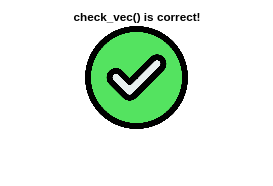

hidden_check_vec();

### 2.2. Mode-$n$ matricization

Similarly to vectorization, as we will see further on, it can be useful to switch from multi-indexing to bilinear-indexing (matrices) when performing certain operations. One way to accomplish this is by means of mode-$n$ matricization. For a fixed mode $n$, the mode-$n$ matricization of a $N$-th order tensor $\underline{\mathbf{X}}\in\mathbb{C}^{I_1\times I_2\times \ldots \times I_N}$, is denoted and defined as the matrix


$$\mathbf{X}_{(k)} \in \mathbb{C}^{I_n \times I_1I_2\cdots I_{n-1}I_{n+1}\cdots I_N},$$


with $I_n$ rows and $I_1I_2\cdots I_{n-1}I_{n+1}\cdots I_N$ columns, with entries 


$$(\mathbf{X}_{(n)})_{i_n,i_1,\cdots, i_{n-1},i_{n+1},\cdots, i_N} = x_{i_1, i_2, \cdots, i_N}.$$


**Question** 

Fill in the function `mode_n_matricization.m. `

**Note**: As previously, for an efficient implementation make use of the built-in Matlab functions (in this case `permute` and `reshape`).

**Debugging tip 1**: To check whether your implementation is correct, you can run the following code block that uses the given test function `hidden_check_mode_n_matricization.p`.

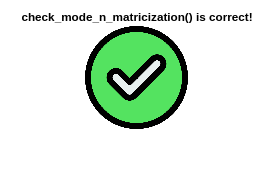

hidden_check_mode_n_matricization();

### 2.3. Mode-$n$ product

Mode-$n$ matricization isolates one mode of the tensor, allowing to perform multiplication between a tensor and a matrix (or a vector). The mode-$n$ product a tensor $\underline{\mathbf{X}}\in\mathbb{C}^{I_1\times I_2\times \ldots \times I_N}$ and a matrix $\mathbf{Y}\in\mathbb{C}^{J\times I_n}$ is denoted and defined as 


$$\underline{\mathbf{Z}} = \underline{\mathbf{X}} \times_n\mathbf{Y}  \in \mathbb{C}^{I_1\times I_2\times \ldots \times J\times \ldots \times I_N},$$


where 


$$z_{i_1, i_2 ,\cdots, j, \cdots , i_N} = \sum_{i_n=1}^{I_n} x_{i_1, i_2 ,\cdots, i_n, \cdots, i_N} y_{j,i_n}.$$


**Question**

Fill in the function` mode_n_product.m. `

**Note**: As previously, for an efficient implementation make use of the built-in Matlab functions (in this case `permute` and `reshape`) as well as your `mode_n_matricization.m`.

**Debugging tip 1**: To check whether your implementation is correct, you can run the following code block that uses the given test function `hidden_check_mode_n_product.p`.

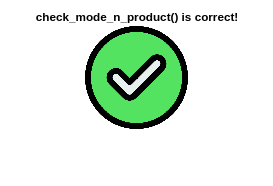

hidden_check_mode_n_product();

### 2.4. Outer and Kronecker product

As a generalization of the matrix case, the outer product of $N$ vectors $\mathbf{x}^{(n)}\in\mathbb{C}^{I_n}, \ n = 1,2,\ldots, N $ is denoted as


$$\mathbf{x}^{(1)} \circ \mathbf{x}^{(2)} \circ \cdots \circ \mathbf{x}^{(N)}  \in \mathbb{C}^{I_1\times I_2 \times \cdots \times I_N},$$


and defined such that    

 
$$(\mathbf{x}^{(1)} \circ \mathbf{x}^{(2)} \circ \cdots \circ \mathbf{x}^{(N)} )_{(i_1,i_2,\ldots,i_N)} = x_{i_1}^{(1)} x_{i_2}^{(2)} \cdots x_{i_N}^{(N)}.$$


The resulting tensor is also known as a rank-1 tensor. A similar and related product is the Kronecker product. The Kronecker product between $N$ vectors $\mathbf{x}^{n}\in\mathbb{C}^{I_n}, \ n = 1,2,\ldots, N $ is a vector denoted as


$$\mathbf{x}^{(1)} \otimes \mathbf{x}^{(2)} \otimes \cdots \otimes \mathbf{x}^{(N)}  \in \mathbb{C}^{I_1 I_2 \cdots I_N},$$


such that 


$$(\mathbf{x}^{(1)} \otimes \mathbf{x}^{(2)} \otimes \cdots \otimes \mathbf{x}^{(N)})_{{(\overline{i_N,i_{N-1},\ldots,i_1})}}= x_{i_1}^{(1)} x_{i_{2}}^{(2)} \cdots x_{i_N}^{(N)}.$$


Outer and Kronecker product are related:


$$\mathrm{vec}(\mathbf{x}^{(1)} \circ \mathbf{x}^{(2)} \circ \cdots \circ \mathbf{x}^{(N)})  = \mathbf{x}^{(N)} \otimes \mathbf{x}^{(N-1)} \otimes
\cdots \otimes \mathbf{x}^{(1)} .$$


**Question**

Prove the above statement. You can use LaTex commands (click on Insert, Equation and then on LaTex equation) or upload an image below. 

*Your answer goes here...*

**Question** 

Fill in the function `outer_product.m `which takes an arbitrary number of vectors and constructs the corresponding outer product. Compute the outer product explicitly.

**Note** Use the [`varargin `syntax in Matlab](https://nl.mathworks.com/help/matlab/ref/varargin.html) to pass an arbitrary number of vectors to a function as a cell array.

**Question**

Fill in the function `outer_product_kron.m `which takes an arbitrary number of vectors and constructs the corresponding outer product. Do not compute the outer product explicitly, use the built-in `kron `function.

**Note** Once more use the [`varargin `syntax in Matlab](https://nl.mathworks.com/help/matlab/ref/varargin.html) to pass an arbitrary number of vectors to a function as a cell array.

**Debugging tip 1**: To check whether your implementations are correct, you can run the following code block that uses the given test functions  `hidden_check_outer_product.p and hidden_check_outer_product_kron.p`.

hidden_check_outer_product();    
hidden_check_outer_product_kron();

### 2.5. Khatri-Rao product

An important subselection of the Kronecker product is the Khatri-Rao product, which is defined as the column-wise Kronecker product: the Khatri-Rao product of $N$matrices $\mathbf{X}^{(n)}\in \mathbb{C}^{I_n \times J}$ is denoted as 


$$\mathbf{X}^{(1)} \odot\mathbf{X}^{(2)} \odot\cdots \odot\mathbf{X}^{(N)}  \in \mathbb{C}^{I_1 I_2 \cdots I_N \times J},$$


such that 


$$(\mathbf{X}^{(1)} \odot\mathbf{X}^{(2)} \odot\cdots \odot\mathbf{X}^{(N)})_{(\overline{i_N,i_{N-1},\ldots,i_1}, \,  j)} = x^{(1)}_{i_1,j} x^{(2)}_{i_2,j} \cdots x^{(N)}_{i_N,j}.$$


As you will see in the upcoming lectures and assignments, the Khatri-Rao product is often encountered when dealing with tensor networks. 

**Question**

Fill in the function khatri_rao`.m `which takes an arbitrary number of matrices and constructs the corresponding Khatri-Rao product.

**Note** Use the [`varargin `syntax in Matlab](https://nl.mathworks.com/help/matlab/ref/varargin.html) to pass an arbitrary number of vectors to a function as a cell array.

**Debugging tip 1**: To check whether your implementation is correct, you can run the following code block that uses the given test function `hidden_check_khatri_rao.p`.

hidden_check_khatri_rao();

### 2.6. Frobenius inner product and norm

Tensors borrow by construction the Frobenius (Euclidean) inner product and norm of vectors, which are respectively denoted and defined for $\underline{\mathbf{X}},\underline{\mathbf{Y}} \in\mathbb{C}^{I_1\times I_2\times \cdots \times I_N}$as :


$$\langle \underline{\mathbf{X}},\underline{\mathbf{Y}} \rangle_{F} = \sum_{i_1=1}^{I_1} \sum_{i_2=1}^{I_2} \cdots \sum_{i_N=1}^{I_N} x^*_{i_1, i_2, \cdots, i_N}\ y_{{i_1, i_2, \cdots, i_N}},$$



$$\vert \vert \underline{\mathbf{X}}\vert\vert_{F} = \sqrt{ \langle\underline{\mathbf{X}},\underline{\mathbf{X}} \rangle_F},$$


where superscript $*$ denotes the complex conjugate. 

**Question**: 

Fill in the functions frob_`inner.m `and `frob_norm.m.`

**Note**: 

As previously, for an efficient implementation make use of the built-in Matlab functions (in this case `permute` and `reshape` but NOT `dot` or `norm`) .

**Debugging tip 1**: To check whether your implementations are correct, you can run the following code block that uses the given test functions  `hidden_check_frob_inner.p and hidden_check_frob_norm.p`.

hidden_check_frob_inner();   
hidden_check_frob_norm();

### 2.7. Tensor network diagrams

When dealing with higher-order tensors, intuition can fail, and it becomes useful to have a graphical tool at disposal.  Borrowing from [3], tensors can be represented graphically by nodes of any geometrical shape (e.g., circles, squares, dots), while each outgoing line (“edge”, “leg”,“arm”) from a node represents the indices of a specific mode. For example a scalar is represented by a dot (zero modes), a vector by a dot with one outward edge (one mode), a matrix by a dot with two outward edges (two modes) etc., see the figure below

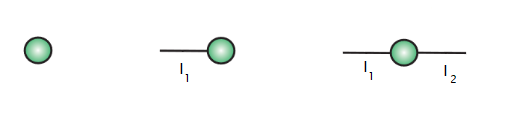

In this notation, a contraction (summing over one index), is represented simply by joining two edges. For example, a standard matrix-vector multiplication $\mathbf{A}\mathbf{x} \in \mathbb{C}^{I_1}$ where $\mathbf{A}\in \mathbb{C}^{I_1\times I_2}$ and $\mathbf{x} \in \mathbb{C}^{I_2}$ can be represented as

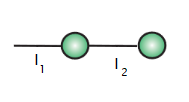

Since $I_1$is the only free edge, the output is a $I_1$-long vector. Similarly, more complex operations can be represented.

In the following exercise you are given either a contraction formula or a tensor network diagram. In the first case, draw the tensor network diagram that corresponds to the given contraction (you can use LaTex commands (click on Insert, Equation and then on LaTex equation) or upload an image). In the second case, do the opposite, i.e. deduce the contraction formula from the diagram and write down the order and the dimensions of all the tensors as well as of the resulting tensor (i.e. is it a scalar, vector, matrix, etc.).

**Question**

Given a square matrix $\mathbf{A}\in \mathbb{C}^{I_1\times I_1}$, the trace operator $\mathrm{trace}(\cdot)$is defined such that $\mathrm{trace}(\mathbf{A}) = \sum_{i_1=1}^{I_1} a_{i_1 , i_1}$. Draw the corresponding tensor network diagram.

*Your answer goes here...*

**Question**

Given the following tensor network diagram, what contraction does this represent (write down the formula)? What are the dimensions and order of the various tensors?

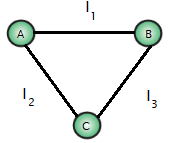

*Your answer goes here...*

**Question**

Given a matrix $\mathbf{A}\in \mathbb{C}^{I_1\times I_2}$, the Singular Value Decomposition uncouples it as $\mathbf{A} = \mathbf{U}\mathbf{S}\mathbf{V}^\mathrm{T}$, where $\mathbf{U}\in\mathbb{C}^{I_1\times R}$ is a (unitary) matrix, $\mathbf{S}\in\mathbb{C}^{R \times R}$ is a (diagonal) matrix, and $\mathbf{V}\in\mathbb{C}^{I_2\times R}$ is (unitary) matrix. Draw the SVD of $\mathbf{A}$.

*Your answer goes here...*

**Question**

Draw the mode-$4$ product between the tensor $\underline{\mathbf{X}} \in \mathbb{C}^{I_1\times I_2\times \cdots \times I_5}$ and the matrix $\mathbf{Y}\in\mathbb{C}^{I_4\times J}$.

*Your answer goes here...*

**Question**

Given the following tensor network diagram, what contraction does this represent (write down the formula)? What are the dimensions and order of the various tensors?

             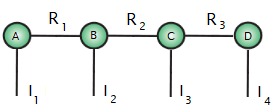

*Your answer goes here...*

## 3. Prepare results for submission

Uncomment the following code lines and run the code to prepare the .pdf file for submission. (Running this code block might take a while.)

% hidden_publish_results('assignment_1_submission.pdf', ...
% 'assignment_1.mlx', 'utils', ...
% {'frob_inner.m', 'frob_norm.m', 'Khatri_rao.m', ...
% 'mode_n_matricization.m', 'mode_n_product.m', ...
% 'outer_product.m', 'outer_product_kron.m', 'vec.m'})

## References

[1] Tamara G. Kolda, Brett W. Bader. “Tensor Decompositions and Applications”. In: SIAM Rev. 51.3 (Aug. 2009), 455–500. issn: 0036-1445. doi: 10.1137/07070111X. url: https: //doi.org/10.1137/07070111X.

[2] Andrzej Cichocki et al. "Tensor Networks for Dimensionality Reduction and Large-scale Optimization: Part 1 Low-Rank Tensor Decompositions", In: Foundations and Trends® in Machine Learning: Vol. 9: No. 4-5 (2016), pp 249-429. http://dx.doi.org/10.1561/2200000059

[3] Orús, Román. "A practical introduction to tensor networks: Matrix product states and projected entangled pair states." *Annals of physics* 349 (2014): 117-158.